# Principal Component Analysis (PCA)

*Pratheep Kumar Chelladurai*

Github Link: [https://github.com/pratheepkumar1/Principles-of-Color-Science/tree/main/Assignment%2014%20PCA](https://github.com/pratheepkumar1/Principles-of-Color-Science/tree/main/Assignment%2014%20PCA)

% Reading the Dataset
warning('off','all');
SGref_dataset = readtable("ccsg.xlsx");
SG_ref = SGref_dataset{:,5:end};
SGwl = (380:10:730)';

## Question 1

Use the Matlab function **pca** to compute 36 principal components of the CCSG. Make a plot of the first 5 principal components versus wavelength, and label them with a legend. Make a plot of the cumulative percentage of variance explained as a function of number of components.

% Compute the principal components of 36 wavelengths using PCA function
[coeff,score,latent,tsquared,explained,mu] = pca(SG_ref);

% Displaying the principal components
coeff

coeff =      0.018558    -0.016833    -0.026539     0.026127     0.010586     0.062451      0.20489     0.079796     -0.16171     -0.14843      0.15936     -0.20342     -0.32733      0.36054    -0.030566    -0.042695      0.22944      0.53736     -0.15546     -0.11113    -0.010729      0.17108      0.16531     -0.30547     -0.19385     -0.13465    -0.052444     0.058623   -0.0065629    -0.014952    -0.017072    0.0021927    0.0059702    -0.011367    -0.010931    -0.010031
      0.03692    -0.038091    -0.059535     0.059304     0.022931      0.11012       0.3914      0.14572     -0.29806    -0.096113      0.19453     -0.19477     -0.30536      0.22672   -0.0035065     -0.08383   -0.0064515     -0.20552     0.046035     0.058792     0.019072     -0.17563     -0.21497      0.43637      0.23431      0.27599      0.11849     -0.11338   -0.0070973     0.021976     0.042301    -0.014635    -0.009718     0.026335     0.014375     0.017543
     0.076784     -0.08404     -0.11858      0.11565  

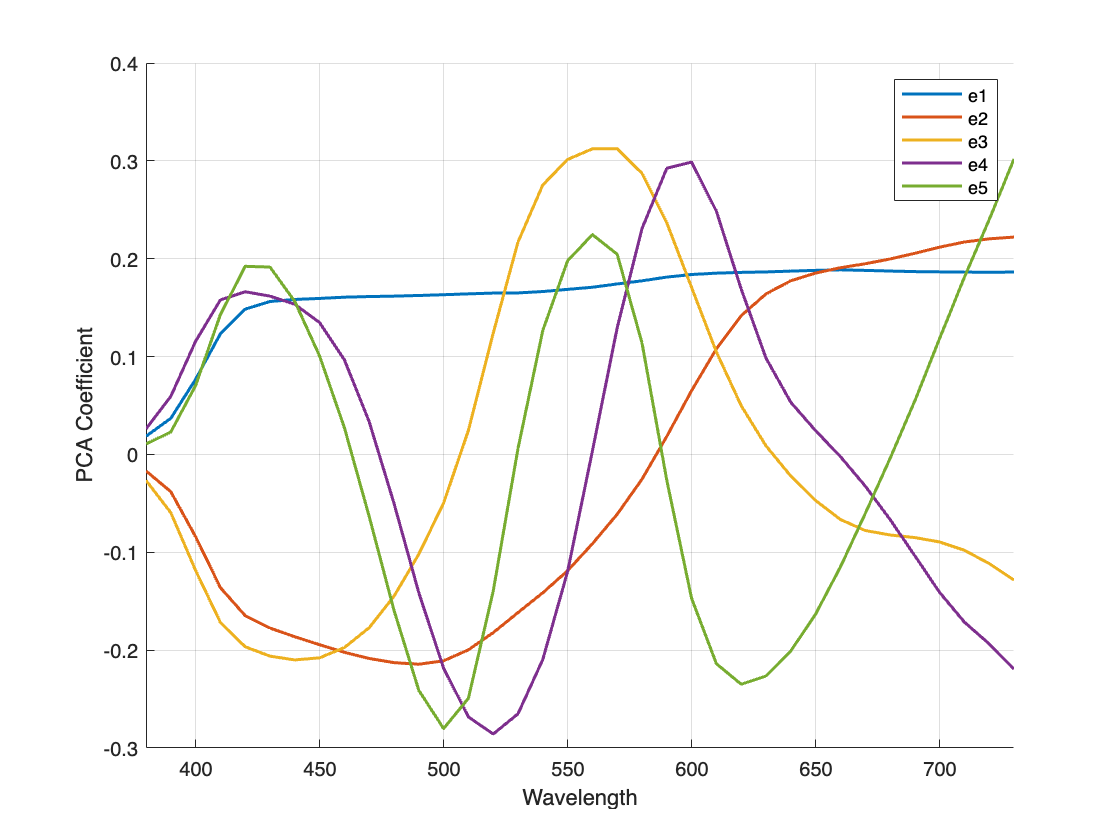

% Plot of the first 5 principal components versus wavelength
figure;
hold on
plot(SGwl,coeff(:,1:5),'LineWidth',1.5);
xlabel('Wavelength');
ylabel('PCA Coefficient');
xlim([380,730]);
legend("e1","e2","e3","e4","e5");
grid on
hold off

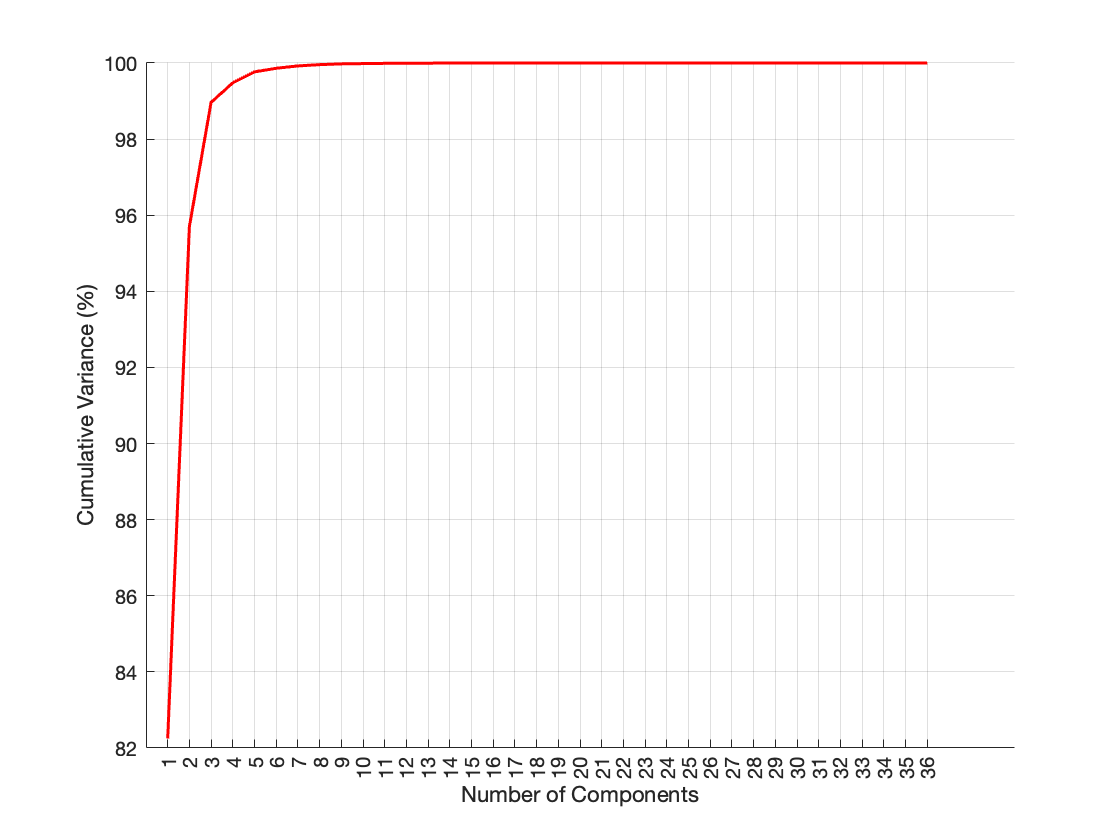

%Calculating & plotting cumulative percentage of the variance
cumsum_var = cumsum(latent);
cumsum_var_percent = (cumsum_var/cumsum_var(end,:))*100;

figure;
hold on
coeff_count = 1:1:36;
plot(coeff_count,cumsum_var_percent,'LineWidth',1.5,'Color','red');
xlabel('Number of Components');
ylabel('Cumulative Variance (%)');
xticks(1:1:36)
grid on
hold off

## Question 2

*Use the ****pca**** coefficients, scores, and mu (mean) to reconstruct the 140 spectra of CCSG patches. Confirm that they match.*

% Reconstruct the 140 spectra of CCSG patches
SG_reconst = score*coeff'+mu

SG_reconst =        0.1123       0.2108       0.4182       0.6675       0.8141       0.8639       0.8793       0.8872       0.8954          0.9       0.9033       0.9072       0.9097       0.9114       0.9145       0.9145       0.9164       0.9175       0.9146        0.916       0.9133       0.9129       0.9116       0.9102       0.9098       0.9093       0.9122       0.9152       0.9183       0.9166       0.9149       0.9142       0.9148       0.9161       0.9171       0.9222
       0.0619       0.1029       0.1506       0.1747       0.1812       0.1847       0.1876       0.1893       0.1894       0.1884       0.1877       0.1872       0.1873       0.1876       0.1884       0.1882       0.1883       0.1884       0.1888       0.1908       0.1916        0.192       0.1911       0.1897       0.1879       0.1856       0.1839       0.1822       0.1808       0.1789        0.177       0.1752       0.1737       0.1722       0.1703       0.1689
       0.0118       0.0123       0.0121       0.0

%Confirm if reconstruct match


## Question 3

*Use only the first ****pca**** coefficient (vector) with the mu to reconstruct the 140 CCSG patches. Compute the DE00 color difference (for 2-deg observer under D65 illuminant) between the original and reconstructed; report the mean and max DE00. *

% Compute CCSG reference LAB values for De00 calcualtion
[num,txt] = xlsread('all_1nm_data.xlsx');
cmf2 = interp1(num(:,1),num(:,6:8),SGwl);
D65 = interp1(num(:,1),num(:,3),SGwl);
SGXYZ_ref = ((cmf2' * diag(D65) * SG_ref') ./ (cmf2(:,2)' * D65) )';
SGLab_ref = xyz2lab(SGXYZ_ref);

% Reconstructed CCSG data with 1st PCA coefficient
SG_reconst_first = score(:,1)*coeff(:,1)'+mu;

% Compute CCSG 1st PCA coefficient data's LAB values
SGXYZ_reconst_first = ((cmf2' * diag(D65) * SG_reconst_first') ./ ...
    (cmf2(:,2)' * D65) )';
SGLab_reconst_first = xyz2lab(SGXYZ_reconst_first);

% DE00 color difference between the original and reconstructed
De00_first = deltaE00(SGLab_reconst_first',SGLab_ref');

% De00 mean
De00_first_mean = mean(De00_first)

De00_first_mean =        18.457



% De00 Max Value
De00_first_max = max(De00_first)

De00_first_max =        39.588


## Question 4

*Reconstruct the 140 CCSG patches with the first two ****pca**** coefficients, and report mean and max DE00.*

% Reconstructed CCSG data with first two PCA coefficient
SG_reconst_second = score(:,1:2)*coeff(:,1:2)'+mu;

% Compute CCSG 2nd PCA coefficient data's LAB values
SGXYZ_reconst_second = ((cmf2' * diag(D65) * SG_reconst_second') ./ ...
    (cmf2(:,2)' * D65) )';
SGLab_reconst_second = xyz2lab(SGXYZ_reconst_second);

% DE00 color difference between the original and reconstructed
De00_second = deltaE00(SGLab_reconst_second',SGLab_ref');

% De00 mean
De00_second_mean = mean(De00_second)

De00_second_mean =        14.365



% De00 Max Value
De00_second_max = max(De00_second)

De00_second_max =        44.107


## Bonus

*Keep going with this series, and determine how many ****pca**** coefficients are necessary to reduce the max DE00 below 0.5.*

% Determine number of pca coefficients to reduce the max DE00 below 0.5.
for i = 1:36
    SG_reconst_f = score(:,1:i)*coeff(:,1:i)'+mu; 
    SGXYZ_reconst_f = ((cmf2' * diag(D65) * SG_reconst_f') ./ ...
        (cmf2(:,2)' * D65) )';
    SGLab_reconst_f = xyz2lab(SGXYZ_reconst_f);
    De00_f = deltaE00(SGLab_reconst_f',SGLab_ref');
    De00_f_max = max(De00_f);
    if(De00_f_max <= 0.5)
        disp("Number of coefficients to minimize De00 to 0.5 is " + i)
        disp("The De00 value at " + i + " is " + De00_f_max);
        break;
    end
end

Number of coefficients to minimize De00 to 0.5 is 11


The De00 value at 11 is 0.34552


## Functions

function   De00=deltaE00(Lab1, Lab2)

%CIELAB Chroma
C1 = sqrt(Lab1(2,:).^2+Lab1(3,:).^2);
C2 = sqrt(Lab2(2,:).^2+Lab2(3,:).^2);

%Lab Prime
mC = (C1+C2)./2;
G=0.5*(1-sqrt((mC.^7)./((mC.^7)+(25.^7))));
LabP1 = [Lab1(1,:) ; Lab1(2,:).*(1+G) ; Lab1(3,:)];
LabP2 = [Lab2(1,:) ; Lab2(2,:).*(1+G) ; Lab2(3,:)];

%Chroma
CP1 = sqrt(LabP1(2,:).^2+LabP1(3,:).^2);
CP2 = sqrt(LabP2(2,:).^2+LabP2(3,:).^2);

%Hue Angle
hP1t = atan2Deg(LabP1(3,:),LabP1(2,:));
hP2t = atan2Deg(LabP2(3,:),LabP2(2,:));

%Add in 360 to the smaller hue angle if absolute value of difference is > 180
hP1 = hP1t + ((hP1t<hP2t)&(abs(hP1t-hP2t)>180)).*360;
hP2 = hP2t + ((hP1t>hP2t)&(abs(hP1t-hP2t)>180)).*360;

%Delta Values
DLP = LabP1(1,:) - LabP2(1,:);
DCP = CP1 - CP2;
DhP = hP1 - hP2;
DHP = 2*(CP1.*CP2).^(1/2).*sinDeg(DhP./2);

%Arithmetic mean of LCh' values
mLP = (LabP1(1,:)+LabP2(1,:))./2;
mCP = (CP1+CP2)./2;
mhP = (hP1+hP2)./2;

%Weighting Functions
SL = 1+(0.015.*(mLP-50).^2)./sqrt(20+(mLP-50).^2);
SC = 1+0.045.*mCP;
T = 1-0.17.*cosDeg(mhP-30)+0.24.*cosDeg(2.*mhP)+0.32.* ...
    cosDeg(3.*mhP+6)-0.2.*cosDeg(4.*mhP-63);
SH = 1+0.015.*mCP.*T;

%Rotation function
RC = 2.*sqrt((mCP.^7)./((mCP.^7)+25.^7));
DTheta = 30.*exp(-((mhP-275)./25).^2);
RT = -sinDeg(2.*DTheta).*RC;

%Parametric factors
kL = 1;
kC = 1;
kH = 1;

De00 = ((DLP./kL./SL).^2+(DCP./kC./SC).^2+(DHP./kH./SH).^2+...
    (RT.*(DCP./kC./SC).*(DHP./kH./SH))).^(1/2);

end

%--------------
function out = sinDeg(in);
out = sin(in.*pi./180);
end

%--------------
function out = cosDeg(in);
out = cos(in.*pi./180);
end

%--------------
function out = atan2Deg(inY,inX);
out = atan2(inY,inX).*180./pi;
out = out+(out<0).*360;

end
